1.1 Generating a Hilbert Curve

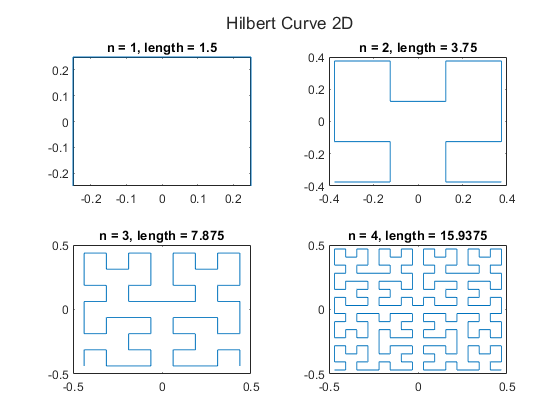

figure;
t = tiledlayout(2, 2);
title(t, "Hilbert Curve 2D");
for n = 1:4
    [X, Y] = hilbert(n);
    ax1 = nexttile;
    plot(X, Y)
    title(ax1, strcat("n = ", num2str(n), ", length = ", num2str(hilbert_length(n))));
end

Length of Hilbert Curve 2D

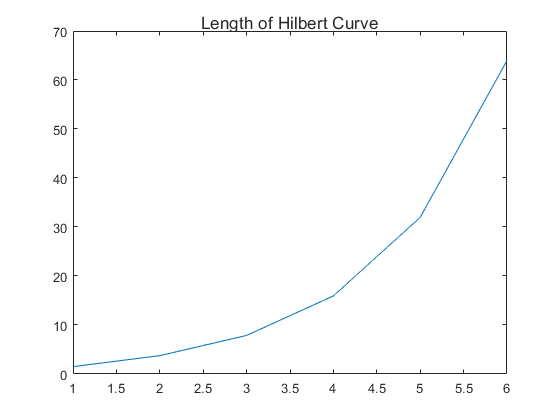

curve_length = zeros(1, 6);
for n = 1:6
    curve_length(n) = hilbert_length(n);
end

figure;
t = tiledlayout(1, 1);
title(t, "Length of Hilbert Curve");
plot((1:6), curve_length);

Total number of turning points

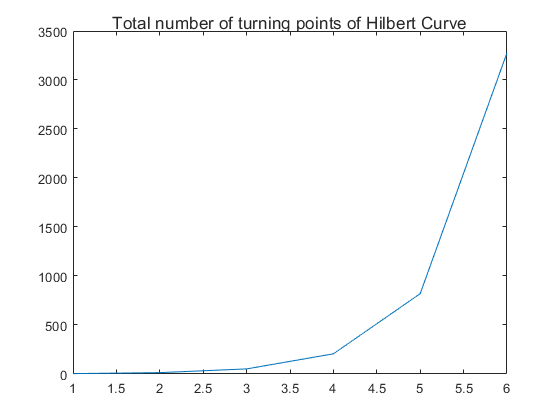

nTurning_points = zeros(1, 6);
for n = 1:6
    nTurning_points(n) = hilbert_points(n);
end

figure;
t = tiledlayout(1, 1);
title(t, "Total number of turning points of Hilbert Curve");
plot((1:6), nTurning_points);

Distance matrix of Hilber 2D with n = 1

d = distance_matrix_hilbert(1, 2)

d =          0    0.5000    0.7071    0.5000
    0.5000         0    0.5000    0.7071
    0.7071    0.5000         0    0.5000
    0.5000    0.7071    0.5000         0


Reconstruct by geometric arguments

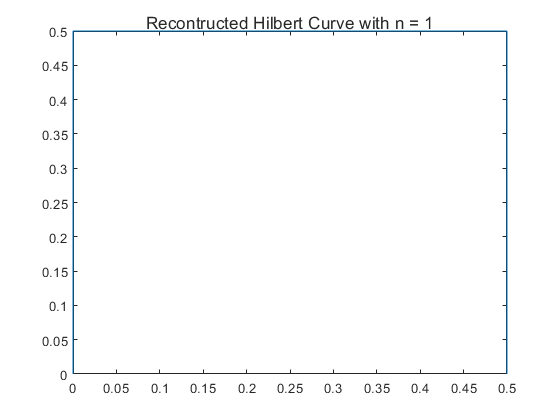


% Get distance of consecutive turning points
path = diag(d, 1);
n = 1;

% Find the first point
x = zeros(1, length(path) + 1);
y = zeros(1, length(path) + 1);

x(1) = 0;
y(1) = 0;

sign_array = [1 1 -1];

for i=1:length(path)    	       
    if (mod(i, 2) == 0)
        x(i + 1) = x(i) + sign_array(i) * path(i);
        y(i + 1) = y(i);
    else
        x(i + 1) = x(i) ;
        y(i + 1) = y(i) + sign_array(i) * path(i);
    end  	    	
end

figure;
t = tiledlayout(1, 1);
title(t, "Recontructed Hilbert Curve with n = 1");
plot(x, y)

2.1 Some more on Hilbert Curve

The 3D version of Hilbert Curve

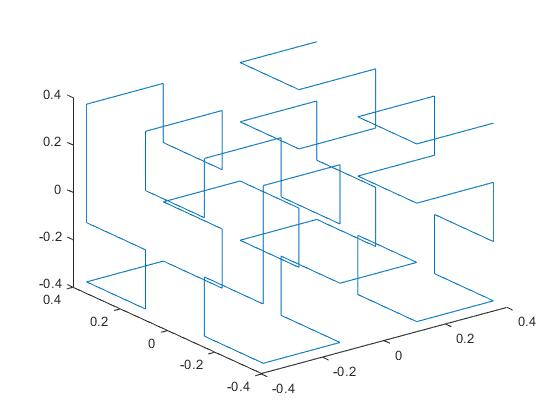

% Plot 3D curve with n = 2
[x, y, z] = hilbert3(2);
figure;
plot3(x, y, z)

Compute the number of turning points

% Number of turning points
nTurning_points = hilbert3_points(2)

nTurning_points = 62

//TODO: Provide a written explanation as to how the 3D code works. What structure is being replicated and how is it moved and rotated?

2.2 Reconstructing the curve

% Three sample sets
set_1 = [ -1 0; -1 1; -1/2 1/2; 0 1; 0 0];
set_2 = [ -1 0; -1 1; -1/2 1/2; 0 1; -1/4 1/4];
set_3 = [ 0 0 1; 0 1 1; -1/2 1/2 1; -1 1 1; -1 0 1; -1 0 0; -1 1 0; -1/2 1/2 0; 0 1 0; 0 0 0];

Solve the Distance Geometry problem using  SVD:

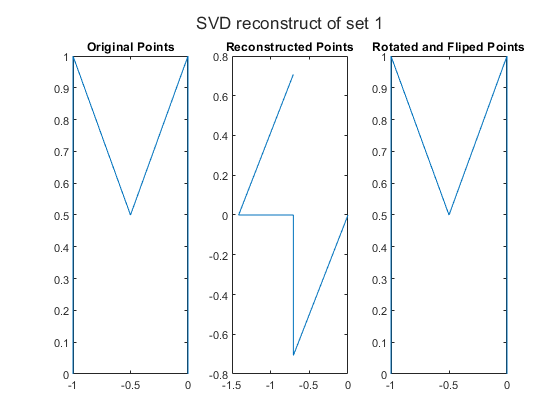

% Create rotation matrix
theta = 135; % to rotate 135 counterclockwise
R = [cosd(theta) -sind(theta); sind(theta) cosd(theta)];


% The distance matrix of set 1
d = distance_matrix(set_1);
X = svd_reconstruct(d);


% Plots
figure;
t = tiledlayout(1,3);
title(t, "SVD reconstruct of set 1");

ax1 = nexttile;
plot(set_1(:,1), set_1(:, 2));
title(ax1,'Original Points');

ax2 = nexttile;
plot(X(:,1), X(:, 2));
title(ax2,'Reconstructed Points');

ax3 = nexttile;
for i = 1:length(X)
    X(i,:) =  X(i,:) * R; 
    X(i, 1) = -X(i, 1); 
end
plot(X(:,1), X(:, 2));
title(ax3,'Rotated and Fliped Points');

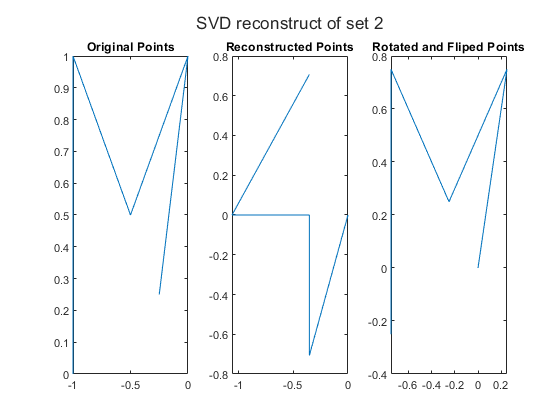


% The distance matrix of set 2
d = distance_matrix(set_2);
X = svd_reconstruct(d);

% Create rotation matrix
theta = 135; % to rotate 135 counterclockwise
R = [cosd(theta) -sind(theta); sind(theta) cosd(theta)];

% Plots
figure;
t = tiledlayout(1,3);
title(t, "SVD reconstruct of set 2");

ax1 = nexttile;
plot(set_2(:,1), set_2(:, 2));
title(ax1,'Original Points');

ax2 = nexttile;
plot(X(:,1), X(:, 2));
title(ax2,'Reconstructed Points');

ax3 = nexttile;
for i = 1:length(X)
    X(i,:) =  X(i,:) * R;
    X(i, 1) = -X(i, 1);    
end

plot(X(:,1), X(:, 2));
title(ax3,'Rotated and Fliped Points');


% The distance matrix of set 3
d = distance_matrix(set_3);

d =          0    1.0000    0.7071    1.4142    1.0000    1.4142    1.7321    1.2247    1.4142    1.0000
    1.0000         0    0.7071    1.0000    1.4142    1.7321    1.4142    1.2247    1.0000    1.4142
    0.7071    0.7071         0    0.7071    0.7071    1.2247    1.2247    1.0000    1.2247    1.2247
    1.4142    1.0000    0.7071         0    1.0000    1.4142    1.0000    1.2247    1.4142    1.7321
    1.0000    1.4142    0.7071    1.0000         0    1.0000    1.4142    1.2247    1.7321    1.4142
    1.4142    1.7321    1.2247    1.4142    1.0000         0    1.0000    0.7071    1.4142    1.0000
    1.7321    1.4142    1.2247    1.0000    1.4142    1.0000         0    0.7071    1.0000    1.4142
    1.2247    1.2247    1.0000    1.2247    1.2247    0.7071    0.7071         0    0.7071    0.7071
    1.4142    1.0000    1.2247    1.4142    1.7321    1.4142    1.0000    0.7071         0    1.0000
    1.0000    1.4142    1.2247    1.7321    1.4142    1.0000    1.4142    0.7071    1.0

X = svd_reconstruct(d);

X =    -0.6033    0.7975   -0.0000
   -1.1672    0.3710   -0.7071
   -1.1672    0.3710    0.0000
   -1.7312   -0.0556    0.0000
   -1.1672    0.3710    0.7071
   -0.5640   -0.4266    0.7071
   -1.1279   -0.8531    0.0000
   -0.5640   -0.4266    0.0000
   -0.5640   -0.4266   -0.7071
         0         0         0


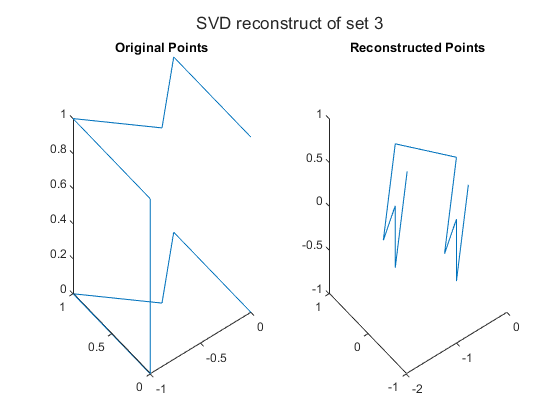


% Plots
figure;
t = tiledlayout(1,2);
title(t, "SVD reconstruct of set 3");

ax1 = nexttile;
plot3(set_3(:,1), set_3(:, 2), set_3(:,3));
title(ax1,'Original Points');

ax2 = nexttile;
plot3(X(:,1), X(:, 2), X(:, 3));
title(ax2,'Reconstructed Points');

Solve the Distance Geometry problem using  Schur

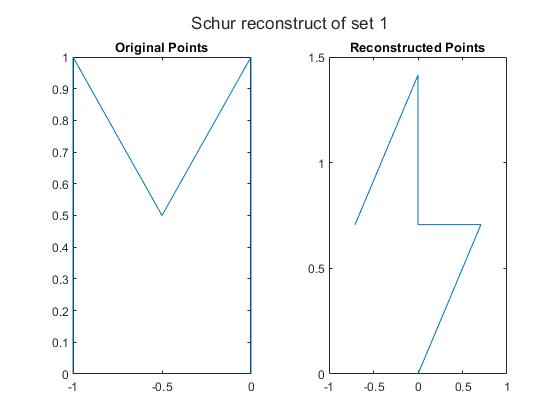

% The distance matrix of set 1
d = distance_matrix(set_1);
X = schur_reconstruct(d);

% Plots
figure;
t = tiledlayout(1,2);
title(t, "Schur reconstruct of set 1");

ax1 = nexttile;
plot(set_1(:,1), set_1(:, 2));
title(ax1,'Original Points');

ax2 = nexttile;
plot(X(:,1), X(:, 2));
title(ax2,'Reconstructed Points');

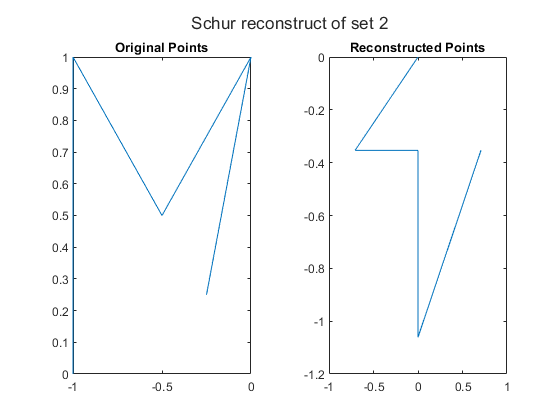


% The distance matrix of set 2
d = distance_matrix(set_2);
X = schur_reconstruct(d);

% Plots
figure;
t = tiledlayout(1,2);
title(t, "Schur reconstruct of set 2");

ax1 = nexttile;
plot(set_2(:,1), set_2(:, 2));
title(ax1,'Original Points');

ax2 = nexttile;
plot(X(:,1), X(:, 2));
title(ax2,'Reconstructed Points');

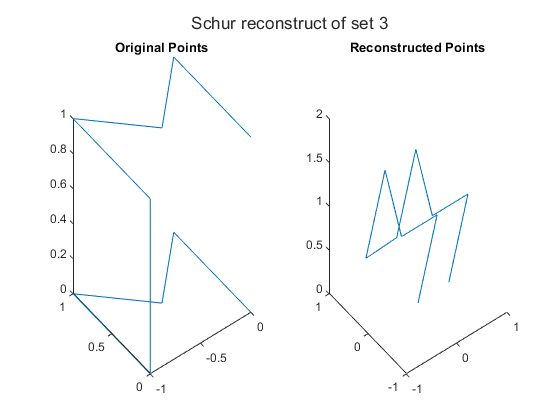


% The distance matrix of set 3
d = distance_matrix(set_3);
X = schur_reconstruct(d);

% Plots
figure;
t = tiledlayout(1,2);
title(t, "Schur reconstruct of set 3");

ax1 = nexttile;
plot3(set_3(:,1), set_3(:, 2), set_3(:,3));
title(ax1,'Original Points');

ax2 = nexttile;
plot3(X(:,1), X(:, 2), X(:, 3));
title(ax2,'Reconstructed Points');

//TODO: Consider rotation

Reconstruct the 2D Hilbert Curve

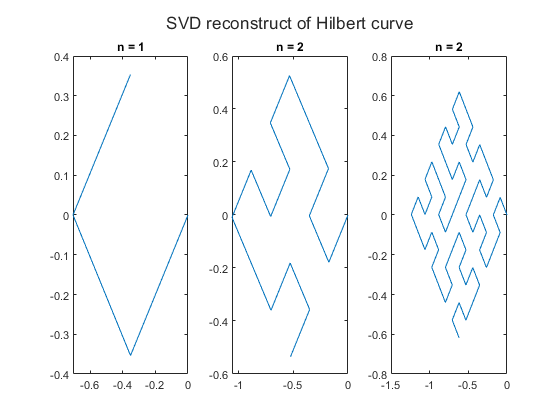


% Plots
figure;
t = tiledlayout(1,3);
title(t, "SVD reconstruct of Hilbert curve");

% Hilbert Curve n = 1
d = distance_matrix_hilbert(1, 2);
X = svd_reconstruct(d);

ax1 = nexttile;
plot(X(:,1), X(:, 2));
title(ax1,'n = 1');

% Hilbert Curve n = 2
d = distance_matrix_hilbert(2, 2);
X = svd_reconstruct(d);

ax2 = nexttile;
plot(X(:,1), X(:, 2));
title(ax2,'n = 2');

% Hilbert Curve n = 3
d = distance_matrix_hilbert(3, 2);
X = svd_reconstruct(d);

ax3 = nexttile;
plot(X(:,1), X(:, 2));
title(ax3,'n = 2');

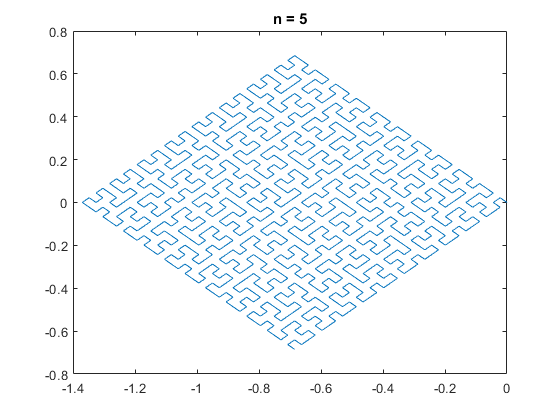



% Hilbert Curve n = 5
figure;
d = distance_matrix_hilbert(5, 2);
X = svd_reconstruct(d);


plot(X(:,1), X(:, 2));
title('n = 5');

Plot singular value of SVD

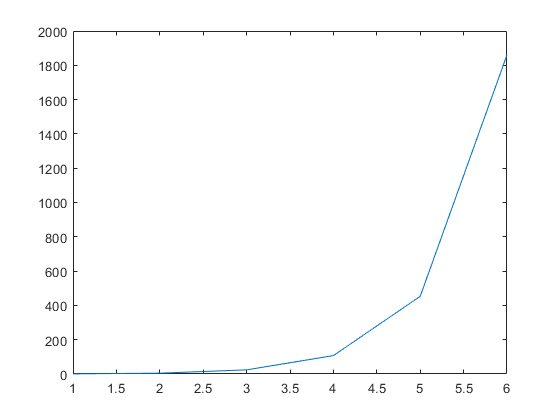

s_values = [];
iteration = 1:6;
for i = 1:length(iteration)
    d = distance_matrix_hilbert(i, 2);
    % Length of  distance matrix
    n = length(d);

    % Calculate M = X * transpose(X)
    % M = (m(i,j) for i,j = 1, ... n-1))
    M = zeros(n, n);

    % SVD method to reconstruct coordinates
    for i = 1:n
        for j = 1:n
            M(i, j) = (d(i, n) ^ 2 - d(i, j) ^ 2 + d(j, n) ^ 2)/2;
        end
    end

    s = svd(M);
   
    s_values = [s_values max(s)];
end

figure;
plot(iteration, s_values)

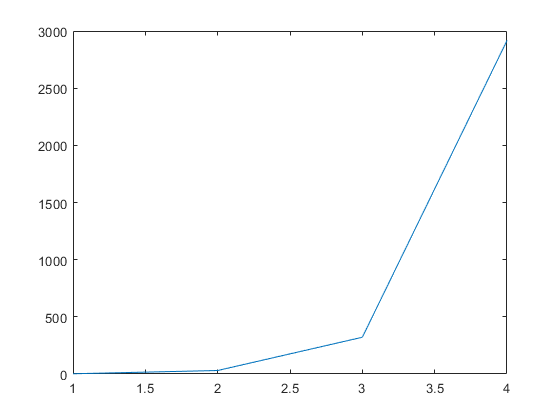


s_values = [];
iteration = 1:4;
for i = 1:length(iteration)
    d = distance_matrix_hilbert(i, 3);
    % Length of  distance matrix
    n = length(d);

    % Calculate M = X * transpose(X)
    % M = (m(i,j) for i,j = 1, ... n-1))
    M = zeros(n, n);

    % SVD method to reconstruct coordinates
    for i = 1:n
        for j = 1:n
            M(i, j) = (d(i, n) ^ 2 - d(i, j) ^ 2 + d(j, n) ^ 2)/2;
        end
    end

    s = svd(M);
   
    s_values = [s_values max(s)];
end

figure;
plot(iteration, s_values)

LLS Build Up algorithm on three set of nodes

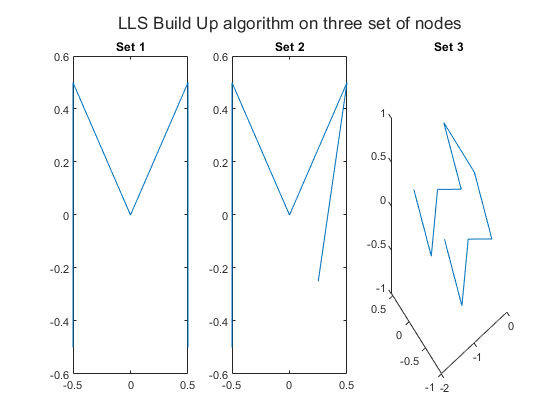

% Plots
figure;
t = tiledlayout(1,3);
title(t, "LLS Build Up algorithm on three set of nodes");

% Set 1
d = distance_matrix(set_1);
X = build_up_LLS(d, 2);

ax1 = nexttile;
plot(X(:,1), X(:, 2));
title(ax1,'Set 1');

% Set 2
d = distance_matrix(set_2);
X = build_up_LLS(d, 2);

ax2 = nexttile;
plot(X(:,1), X(:, 2));
title(ax2,'Set 2');

% Set 3
d = distance_matrix(set_3);
X = build_up_LLS(d, 3);

ax3 = nexttile;
plot3(X(:,1), X(:, 2), X(:, 3));
title(ax3,'Set 3');

LLS Build Up algorithm on Hilbert 2D and 3D with n = 2, 3, 4

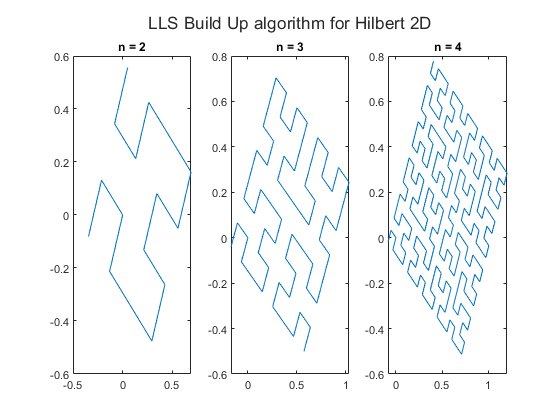

% Plots
figure;
t = tiledlayout(1,3);
title(t, "LLS Build Up algorithm for Hilbert 2D");

% 2D with n = 2
d = distance_matrix_hilbert(2, 2);
X = build_up_LLS(d, 2);

ax1 = nexttile;
plot(X(:,1), X(:, 2));
title(ax1,'n = 2');

% 2D with n = 3
d = distance_matrix_hilbert(3, 2);
X = build_up_LLS(d, 2);

ax2 = nexttile;
plot(X(:,1), X(:, 2));
title(ax2,'n = 3');

% 2D with n = 4
d = distance_matrix_hilbert(4, 2);
X = build_up_LLS(d, 2);

ax3 = nexttile;
plot(X(:,1), X(:, 2));
title(ax3,'n = 4');

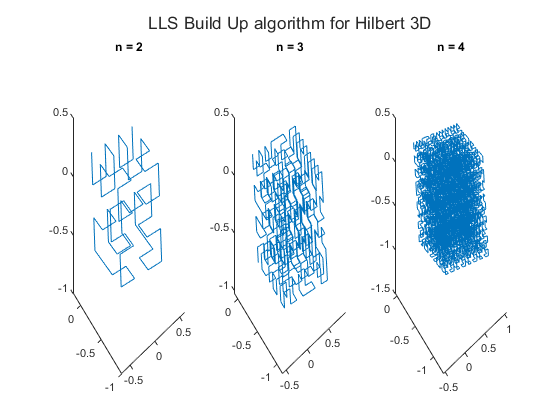

% Plots
figure;
t = tiledlayout(1,3);
title(t, "LLS Build Up algorithm for Hilbert 3D");

% 3D with n = 2
d = distance_matrix_hilbert(2, 3);
X = build_up_LLS(d, 3);

ax1 = nexttile;
plot3(X(:,1), X(:, 2), X(:, 3));
title(ax1,'n = 2');

% 3D with n = 3
d = distance_matrix_hilbert(3, 3);
X = build_up_LLS(d, 3);

ax2 = nexttile;
plot3(X(:,1), X(:, 2), X(:, 3));
title(ax2,'n = 3');

% 3D with n = 4
d = distance_matrix_hilbert(4, 3);
X = build_up_LLS(d, 3);

ax3 = nexttile;
plot3(X(:,1), X(:, 2), X(:, 3));
title(ax3,'n = 4');

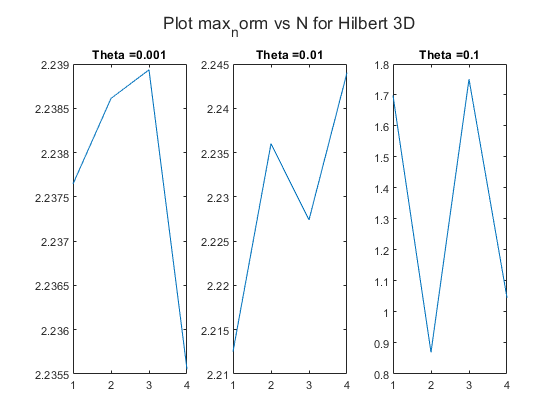

theta = [0.001 0.01 0.1];
n = 1:4;

dim = 3;
max_norm = zeros(1, 4);



figure;
t = tiledlayout(1,3);
title(t, "Plot max_norm vs N for Hilbert 3D");

for j = 1:length(theta)
    for i = 1:length(n)
        d = distance_matrix_hilbert(n, dim);
        d_noise = distance_matrix_wNoise(d, theta(j));
        
        X = build_up_LLS(d, dim);
        X_noise = build_up_LLS(d_noise, dim);
        
        max_norm(i) = find_max_norm(X, X_noise);
    end
    
    ax1 = nexttile;
    plot(n, max_norm);
    title(ax1, strcat("Theta = ", num2str(theta(j))));
end

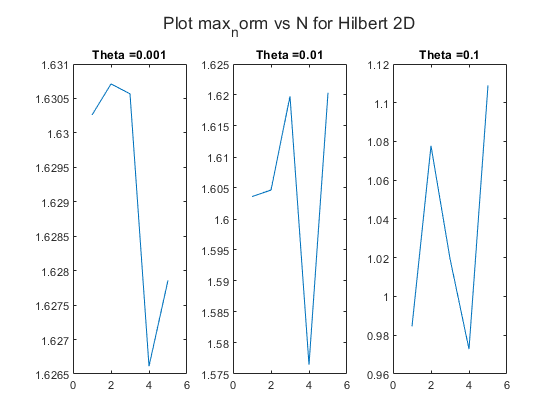

theta = [0.001 0.01 0.1];
n = 1:5;

dim = 2;
max_norm = zeros(1, length(n));



figure;
t = tiledlayout(1,3);
title(t, "Plot max_norm vs N for Hilbert 2D");

for j = 1:length(theta)
    for i = 1:length(n)
        d = distance_matrix_hilbert(n, dim);
        d_noise = distance_matrix_wNoise(d, theta(j));
        
        X = build_up_LLS(d, dim);
        X_noise = build_up_LLS(d_noise, dim);
        
        max_norm(i) = find_max_norm(X, X_noise);
    end
    
    ax1 = nexttile;
    plot(n, max_norm);
    title(ax1, strcat("Theta = ", num2str(theta(j))));
end